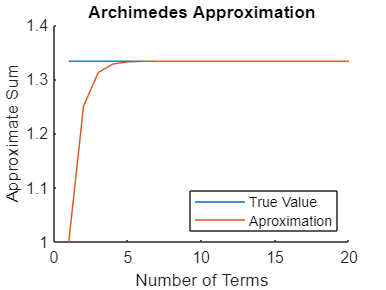

clc; clear; close all;

a = 1;
r = 1 / 4;
n = 20;

x_vec = 1:n;
true_vec = a / (1 - r) .* ones(1, n);

% series_vec = nan(1, n);
% for i = 1:n
%     series_vec(i) = a * r ^ (i - 1);
% end

% alternatively:
series_vec = a * r .^ ((1:n) - 1);

% sum(series_vec);

% cumulative sum
cum_series_vec = cumsum(series_vec);

% plot
figure; % starts a new plot
hold on; % allows us to plot multiple curves
plot(x_vec, true_vec);
plot(x_vec, cum_series_vec);
hold off;

title("Archimedes Approximation")
legend("True Value", "Aproximation", 'Location', 'Southeast');
xlabel("Number of Terms");
ylabel("Approximate Sum");
hold off;